Filtro Sobel usando convolución

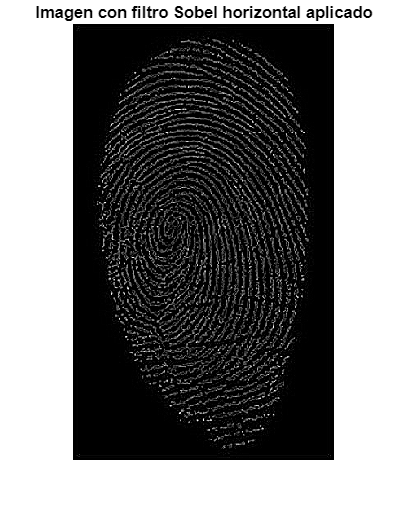

% Leer la imagen en escala de grises
img = imread('1366_2000.jpg');
img=rgb2gray(img);
img = double(img);

% Definir el kernel Sobel horizontal
kernel = [0 1 0; 1 -4 1 ; 0 1 0];

% Obtener el tamaño de la imagen y el kernel
[m,n] = size(img);
[km,kn] = size(kernel);

% Invertir el kernel horizontal y verticalmente
kernel = flipud(fliplr(kernel));

% Inicializar la matriz de salida
output = zeros(m,n);

% Realizar la convolución
for i = 1:m-km+1
    for j = 1:n-kn+1
        % Obtener la región de la matriz de entrada que coincide con el kernel
        region = img(i:i+km-1,j:j+kn-1);
        % Realizar la multiplicación punto a punto entre la región y el kernel invertido
        product = region .* kernel;
        % Sumar los productos y almacenar el valor en la ubicación correspondiente en la matriz de salida
        output(i+floor(km/2),j+floor(kn/2)) = sum(product(:));
    end
end

% Mostrar la imagen resultante
figure;
imshow(uint8(output));
title('Imagen con filtro Sobel horizontal aplicado');

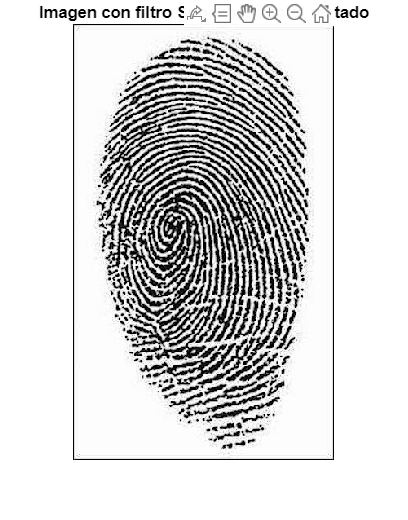


output=uint8(output);
img=uint8(img);
final=img-output;
imshow(final);
title('Imagen con filtro Sobel horizontal restado');

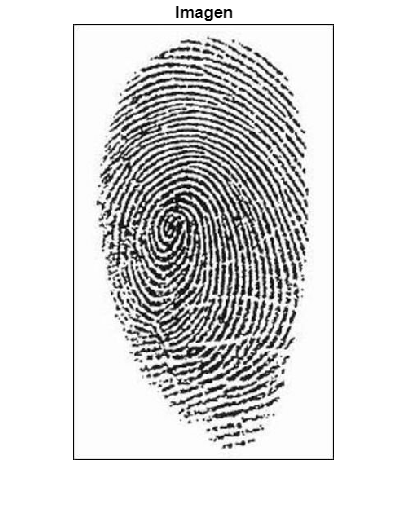

imshow(img);
title('Imagen');